# 1.3.09 Проведение расчетов в символьном виде и оптимизация формул

**Самостоятельная работа????**

Периодическая функция с периодом T=2L может быть разложена в тригонометрический ряд Фурье вида:


$$f\left(x\right)=\frac{a_0 }{2}+\sum_{k=1}^{\infty } \left(a_k \cdot \mathrm{cos}\left(\frac{\pi kx}{L}\right)+b_k \cdot \mathrm{sin}\left(\frac{\pi kx}{L}\right)\right)$$


где $a_0$, $a_k$и $b_k$ являеются коэффициентами Фурье, и определяются по формулам Эйлера-Фурье:


$$\begin{cases} 
a_k =\frac{1}{L}\int_{-L}^L f\left(x\right)\mathrm{cos}\left(\frac{\pi kx}{L}\right)\mathrm{dx},k=0,1,2\;\ldotp \ldotp \ldotp \ldotp, \\
b_k =\frac{1}{L}\int_{-L}^L f\left(x\right)\mathrm{sin}\left(\frac{\pi kx}{L}\right)\textrm{dx},k=0,1,2\;\ldotp \ldotp \ldotp \ldotp. 
\end{cases}$$



$$a_0 =\frac{1}{L}\int_{-L}^L f\left(x\right)\mathrm{dx}$$



$$a_k =\frac{1}{L}\int_{-L}^L f\left(x\right)\mathrm{cos}\left(\frac{\pi kx}{L}\right)\mathrm{dx},k=0,1,2\;\ldotp \ldotp \ldotp \ldotp$$



$$b_k =\frac{1}{L}\int_{-L}^L f\left(x\right)\mathrm{sin}\left(\frac{\pi kx}{L}\right)\textrm{dx},k=0,1,2\;\ldotp \ldotp \ldotp \ldotp$$


Для заданной функции$f\left(x\right)$ найдите коэффициенты Фурье в аналитическом виде, разложиет функцию в ряды Фурье с различным количеством членов ряда: 3, 5, 7, 50. Постройте график функции $f\left(x\right)$ и ее разложений в ряд Фурье с различным числом членов ряда.

#### 1. Создайте символьные переменные:

 $x$- независимая переменная, $k$- количество членов ряда, $\textrm{pi}$ - символьное обозначение числа $\pi$.

syms x k pi

#### 2. Задайте кусочно-линейную функцию $f\left(x\right)$

Воспользуйтесь командой `piecewise()`, проверить правильность функции можно построив ее график командой `fplot()`

f_x=piecewise(-1<=x<0,x+1,0<=x<1,x-1)
fplot(f_x)

#### 3. Вычислите коэффициенты Фурье

% Задайте период функции T
T=2;
% Вычислите L
L=T/2;
% Найдите a_0, a_k, b_k
a_0=1/L*int(f_x,x,-1,1)
a_k=1/L*int(f_x*cos(k*x*pi/L),x,-1,1)
b_k=1/L*int(f_x*sin(k*x*pi/L),x,-1,1)

#### 4. Разложите функцию в ряды Фурье с количеством членов ряда 3, 5, 7, 50

sum3 = a_0/L + symsum(a_k*cos(k*x*pi/L) + b_k*sin(k*x*pi/L),k,1,3)

$$sum3 = -\frac{2\,\sin\left(\pi \,x\right)}{\pi }-\frac{\sin\left(2\,\pi \,x\right)}{\pi }-\frac{2\,\sin\left(3\,\pi \,x\right)}{3\,\pi }$$

sum5 = a_0/L + symsum(a_k*cos(k*x*pi/L) + b_k*sin(k*x*pi/L),k,1,5)

$$sum5 = -\frac{2\,\sin\left(\pi \,x\right)}{\pi }-\frac{\sin\left(2\,\pi \,x\right)}{\pi }-\frac{2\,\sin\left(3\,\pi \,x\right)}{3\,\pi }-\frac{\sin\left(4\,\pi \,x\right)}{2\,\pi }-\frac{2\,\sin\left(5\,\pi \,x\right)}{5\,\pi }$$

sum7 = a_0/L + symsum(a_k*cos(k*x*pi/L) + b_k*sin(k*x*pi/L),k,1,7)

$$sum7 = -\frac{2\,\sin\left(\pi \,x\right)}{\pi }-\frac{\sin\left(2\,\pi \,x\right)}{\pi }-\frac{2\,\sin\left(3\,\pi \,x\right)}{3\,\pi }-\frac{\sin\left(4\,\pi \,x\right)}{2\,\pi }-\frac{2\,\sin\left(5\,\pi \,x\right)}{5\,\pi }-\frac{\sin\left(6\,\pi \,x\right)}{3\,\pi }-\frac{2\,\sin\left(7\,\pi \,x\right)}{7\,\pi }$$

sum50 = a_0/L + symsum(a_k*cos(k*x*pi/L) + b_k*sin(k*x*pi/L),k,1,50)

#### 5. Постройте на одних осях график функции $f\left(x\right)$ и полученные разложения в ряд.

Для удобного исследования графика задайте лимиты по оси $x\;\left\lbrack -2;2\right\rbrack$

fplot(sum3),grid, hold,

Current plot held


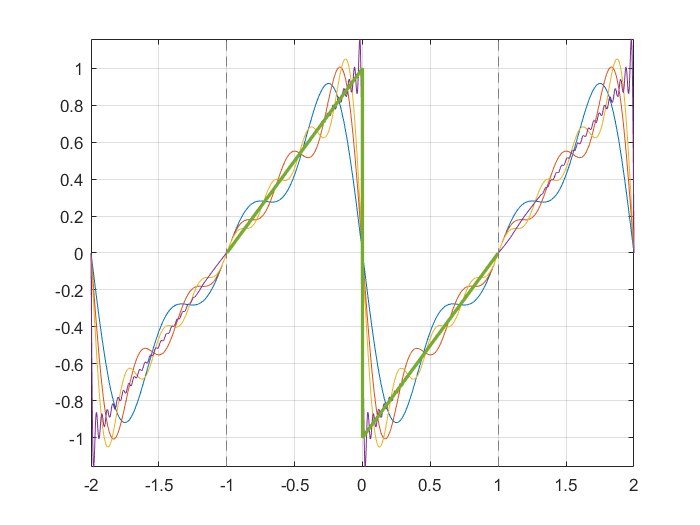

fplot(sum5)
fplot(sum7)
fplot(sum50)
fplot(f_x,'LineWidth',2)
xlim([-2,2])

%  axis equal